# Part 5: Predictive Modeling

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

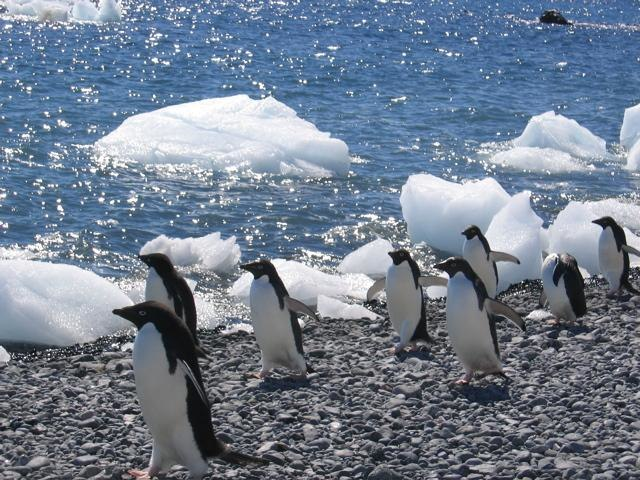

March of the (Adelie) [penguins](https://commons.wikimedia.org/wiki/File:The_World_Factbook_-_Antarctica_-_Flickr_-_The_Central_Intelligence_Agency_(4).jpg).

You should go through all previous statistics livescripts before completing this one. This block of code will add `penguins` to your workspace if it's not already there, clean it up, and pull out a few relevant variables for this section: 

filename = "penguins.csv";
penguins = readtable(filename);
penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);
penguins1 = rmmissing(penguins);
chinstrap = penguins1(penguins1.species == "Chinstrap",:);
gentoo = penguins1(penguins1.species == "Gentoo",:); 
adelie = penguins1(penguins1.species == "Adelie",:);

We can also examine our data by using some of the visualizations we looked at in the biosciences data module***(add link to module 2 Github)***, like the [**scatter plot**](https://www.mathworks.com/help/matlab/ref/scatter.html). Recall that a scatter plot lets us look at how two variables may be related to one another. For example, let's see how flipper length and body mass might be related. 

  Use` scatter()` to create a scatter plot that plots penguin body mass on the x-axis, and flipper length on the y-axis (hint: use `penguins1.body_mass_g `as the first input) : 

Labels:

ylabel("Flipper Length(mm)")
xlabel("Body Mass (g)")

 What do you notice about the relationship between body mass and flipper length here?

Looking at this plot, we might say "It seems like as flipper length increases, body mass increases as well." How do we confirm this? Basically, we try to find a model that best describes the data. 

## Fitting a curve to data (predictive modeling)

### Linear regression

You"ve probably heard ["the line of best fit"](https://en.wikipedia.org/wiki/Simple_linear_regression), which is a line that best describes the linear relationship between x and y. Finding a best-fit line is the most straightforward form of [predictive modeling](https://en.wikipedia.org/wiki/Predictive_modelling), and it's easy to do in MATLAB®. We can use a built-in function called [`fit()`](https://www.mathworks.com/help/curvefit/fit.html) to fit a model to our data! The model that describes a line is y=a*x+b. In the case of our data, we know x (body mass) and y (flipper length), and `fit()` helps us to find the best values of a (slope) and b (y-intercept) that create a line that best describes our data. 

The fit function takes in x, y, and the type of model you want to use, which in the case of a line, is "`poly1"`: 

linear_model = fit(penguins1.body_mass_g, penguins1.flipper_length_mm,"poly1")

The values `p1` and `p2` here are the best values of a and b that were determined by this function. 

Let"s try plotting this best-fit line on our data. 

The [`plot()` ](https://www.mathworks.com/help/matlab/ref/plot.html)function takes in the model as the first input, and then the values of x and y that you used to fit the model.

plot(linear_model, penguins1.body_mass_g, penguins1.flipper_length_mm)
xlabel("Body mass (g)")
ylabel("Flipper length (mm)")

Ok cool, it looks like this linear model does describe the data in some way. But how well does it describe the data? 

### Goodness of fit

MATLAB will quantify the "[goodness of the fit](https://en.wikipedia.org/wiki/Goodness_of_fit)" for us! All we have to do is tell the `fit()` function to also output how good the fit is, which looks like: 

[linear_model, gof] = fit(penguins1.body_mass_g, penguins1.flipper_length_mm,"poly1")

We are outputting information about how well the model fits the data to a variable called `gof`. There are several outputs here including [`sse`](https://www.mathworks.com/help/deeplearning/ref/sse.html), or [sum squared error](https://en.wikipedia.org/wiki/Residual_sum_of_squares), which is a measure of how much error there is between the real and predicted values. Locate [`rsquare`](https://www.mathworks.com/help/stats/coefficient-of-determination-r-squared.html), which is the [R-squared](https://en.wikipedia.org/wiki/Coefficient_of_determination) value. R-squared is a measure of how well the real values are predicted by the values generated by the model. This is measured by finding the correlation between the predicted and real values (how "in sync" they are; see correlation discussion below). This value is called R. The square of the correlation between predicted and real values tells you how much of the variation in the dataset (real data) is explained by the model, or predicted values. 

The R-squared value can range between 0 and 1. An R-squared value close to 1 means the data is extremely well predicted by the model! 

In this case, our R-squared value is 0.76. Note that what constitutes a "good" R-squared value depends a lot on the field and the question. Since there is so much biological variability that exists, in general, you can't expect R-squared values that are super close to 1. 0.76 is pretty good - it means this model explains over 75% percent of the variance in the data, which is usually considered significant, and therefore a good fit! 

This process of using a linear model to fit our data is also called* linear regression*. So if you've heard that term and been scared by it before, don't be! You've already done it! To learn more about regression, check out this [curriculum module](https://www.mathworks.com/matlabcentral/fileexchange/93435-regression-basics/).

### Try different types of models

You can play around with the different types of models by adjusting the 3rd input to `fit()`. Check out different available model types [here](https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl). The "`poly2"` model type is a quadratic, which you might remember from algebra.

  Try fitting an exponential model using "`exp1"`. Then, try using "`poly2"` to fit a quadratic model (note: you should adjust the "poly1" input).

[test_model, test_gof] = fit(penguins1.body_mass_g, penguins1.flipper_length_mm,"poly1")

  Plot` test_model` as we did above. 

Labels: 

xlabel("Body mass (g)")
ylabel("Flipper length (mm)")

Notice how the R-squared value changes. 

You might notice that when we use other models like `exp1` or `poly2`, the R-squared value barely changes. Going from the first linear model to these more complex models, we are adding more and more parameters to fit the data. The general rule of thumb is to avoid "overfitting" your data. In the most extreme case, this might look like connecting every individual point. That would make it hard for us to predict something from the data - for example, if were given a penguin with a certain flipper length, and want to predict its weight. To avoid overfitting, we usually try to fit the data with as simple a model as possible that still describes the variance in the data. In this case, that is the two-parameter (a, b) regression line.

### Comparisons between species

Biologists often want to make comparisons between species. For example, we can make a plot that shows us what bill depth and bill length look like for each species. 

Let's quickly fit a model to bill length versus depth for each species : 

gent_model = fit(gentoo.bill_length_mm, gentoo.bill_depth_mm, "poly1");
chin_model = fit(chinstrap.bill_length_mm, chinstrap.bill_depth_mm, "poly1");
ad_model = fit(adelie.bill_length_mm, adelie.bill_depth_mm, "poly1");

And then let's plot these models with the data all on one plot: 

plot(gentoo.bill_length_mm, gentoo.bill_depth_mm, "o", SeriesIndex=1)
hold on % turn on hold so we can get everything in one plot 
p1 = plot(gent_model);

plot(chinstrap.bill_length_mm, chinstrap.bill_depth_mm, "o", SeriesIndex=2)
p2 = plot(chin_model);

plot(adelie.bill_length_mm, adelie.bill_depth_mm, "o", SeriesIndex=4)
p3 = plot(ad_model);

hold off

legend("Gentoo", "","Chinstrap","","Adelie","Location","northwest")
xlabel("Bill length (mm)")
ylabel("Bill depth (mm)")

This type of plot can help us understand how the bill length- bill depth ratio differs between species. So now, if we are given a certain bill length and bill depth that was measured in the field, we have a model for how these variables are related in each species, and we can make an educated guess as to which species the given bill length and depth combination is most likely to be from! 

[*Continue to next section (Correlations)*](matlab: edit S6_Correlations.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)